# Solar array Austin

Description: This algorithm plot the capacity factor, energy yield, variation of values for the solar array. 

Developed by Natanael Bolson

Supervised by Prof. Tad Patzek

Energy Geosystems Group -ANPERC - KAUST 01/2022

clc
clear 
close all

%kWh/month starting July 19, 2013
% Inverter 3 from 8/19/2019
% System 1 = 16+16 Renesola Model JC260-24 Bb (260 W) panels. Total peak
% power = 8320W
% System 2  = 24x LG335N1C-V5, 335W panels. Total peak power 8040 W
% Nominal capacity
NC12=8.320/2;%kW % Divided by two as it is 2 arrays
NC3=8.04;%kW

Inverter1 = [...
2021	287	245	468	407	399	449	469	482	484	388	252	213	
2020	273	323	326	425	506	480	508	538	363	396	266	249	
2019	286	266	391	461	396	436	561	535	461	387	241	273	
2018	306	201	463	471	526	497	547	536	343	297	267	240	
2017	319	341	473	469	443	481	543	475	468	444	268	205	
2016	364	479	504	462	424	527	611	496	469	471	242	206	
2015	240	327	409	411	364	486	605	567	502	430	224	272	
2014	318	320	493	495	525	496	556	574	424	427	260	166		];

Inverter2 =[...
2021	328	257	477	406	388	434	457	482	514	445	336	247	
2020	314	332	324	423	492	461	493	532	375	433	337	302	
2019	330	273	405	473	394	429	559	542	490	431	286	335	
2018	346	201	473	480	522	493	549	548	359	324	331	281	
2017	361	353	482	475	438	473	539	476	490	488	323	235	
2016	410	497	514	465	420	519	604	501	496	521	310	220	
2015	293	323	386	400	358	481	598	573	529	468	265	307	
2014	395	328	464	476	506	482	551	561	429	480	338	195	];

Inverter3 = [...
2021	860	608	1062	915	903	1034	1072	1115	1178	1046	852	697	
2020	805	767	753	1002	1190	1134	1206	1282	882	1045	845	856	
2019	0	  0	  0	   0	   0	0	       0	1260   1116	959	    712	921	];

Days=[31 28 31 30 31 30 31 31 30 31 30 31]; 

## Means

M_1=mean(Inverter1(:,2:end))%kWh/month

M_1 =   299.1250  312.7500  440.8750  450.1250  447.8750  481.5000  550.0000  525.3750  439.2500  405.0000  252.5000  228.0000


M_2=mean(Inverter2(:,2:end))

M_2 =   347.1250  320.5000  440.6250  449.7500  439.7500  471.5000  543.7500  526.8750  460.2500  448.7500  315.7500  265.2500


M_3=mean(Inverter3(1:2,2:end))

M_3 = 	1.0e+03 *

    0.8325    0.6875    0.9075    0.9585    1.0465    1.0840    1.1390    1.1985    1.0300    1.0455    0.8485    0.7765



CF=[M_1./(NC12*Days*24)
    M_2./(NC12*Days*24)
    M_3./(NC3*Days*24)
    ]

CF =     0.0966    0.1119    0.1424    0.1503    0.1447    0.1608    0.1777    0.1697    0.1467    0.1309    0.0843    0.0737
    0.1122    0.1146    0.1424    0.1502    0.1421    0.1574    0.1757    0.1702    0.1537    0.1450    0.1054    0.0857
    0.1392    0.1272    0.1517    0.1656    0.1749    0.1873    0.1904    0.2004    0.1779    0.1748    0.1466    0.1298


M_CF=mean(CF')

M_CF =     0.1325    0.1379    0.1638


STD_CF=std(CF')

STD_CF =     0.0337    0.0275    0.0245


MY_CF=mean(M_CF)

MY_CF = 0.1447


STDY_CF=std(M_CF)

STDY_CF = 0.0168

%Yield
M_Yield=MY_CF*24*365

M_Yield = 1.2678e+03

STD_Yield=STDY_CF*24*365

STD_Yield = 146.7843

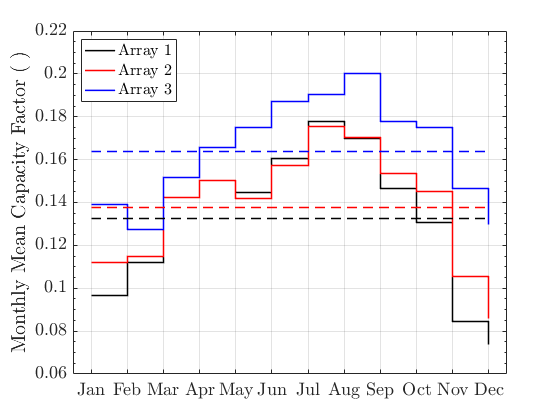


Month=categorical({'Jan','Feb','Mar','Apr','May','Jun','Jul','Aug','Sep','Oct','Nov','Dec'});
figure
stairs(reordercats(Month,cellstr(Month)'),CF(1,:),'k','LineWidth',1.5)
hold on
stairs(reordercats(Month,cellstr(Month)'),CF(2,:),'r','LineWidth',1.5)
stairs(reordercats(Month,cellstr(Month)'),CF(3,:),'b','LineWidth',1.5)
stairs(Month([1 end]),[M_CF(1) M_CF(1)],'--k','LineWidth',1.5)
stairs(Month([1 end]),[M_CF(2) M_CF(2)],'--r','LineWidth',1.5)
stairs(Month([1 end]),[M_CF(3) M_CF(3)],'--b','LineWidth',1.5)
ylabel('Monthly Mean Capacity Factor ( )','Interpreter','latex')
grid on
set(gca,'XMinorTick','on','YMinorTick','on')
set(gca,'Fontsize',18,'TickDir','in','FontWeight','normal','GridAlpha',...
    0.13,'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')
xtickangle(0)
legend('Array 1','Array 2','Array 3','location','NW','interpreter','latex')

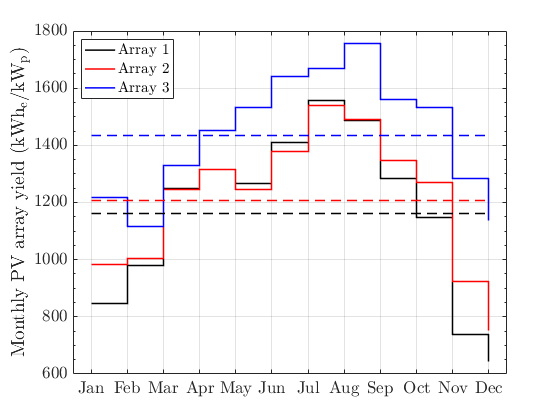

% print('-dpng','-r400','CF_Patzek')

figure
stairs(reordercats(Month,cellstr(Month)'),CF(1,:)*8760,'k','LineWidth',1.5)
hold on
stairs(reordercats(Month,cellstr(Month)'),CF(2,:)*8760,'r','LineWidth',1.5)
stairs(reordercats(Month,cellstr(Month)'),CF(3,:)*8760,'b','LineWidth',1.5)
stairs(Month([1 end]),[M_CF(1) M_CF(1)]*8760,'--k','LineWidth',1.5)
stairs(Month([1 end]),[M_CF(2) M_CF(2)]*8760,'--r','LineWidth',1.5)
stairs(Month([1 end]),[M_CF(3) M_CF(3)]*8760,'--b','LineWidth',1.5)
ylabel('Monthly PV array yield ($\mathrm{kWh_e/kW_p}$)','Interpreter','latex')
grid on
set(gca,'XMinorTick','on','YMinorTick','on')
set(gca,'Fontsize',17,'TickDir','in','FontWeight','normal','GridAlpha',...
    0.13,'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')
xtickangle(0)
legend('Array 1','Array 2','Array 3','location','NW','interpreter','latex')

% print('-dpng','-r400','Yield_Patzek')

## Performance theoretical

CF=[M_1./(Days*24)
    M_2./(Days*24)
    M_3./(Days*24)
    ]*1000

CF = 	1.0e+03 *

    0.4020    0.4654    0.5926    0.6252    0.6020    0.6687    0.7392    0.7061    0.6101    0.5444    0.3507    0.3065
    0.4666    0.4769    0.5922    0.6247    0.5911    0.6549    0.7308    0.7082    0.6392    0.6032    0.4385    0.3565
    1.1190    1.0231    1.2198    1.3313    1.4066    1.5056    1.5309    1.6109    1.4306    1.4052    1.1785    1.0437


% Average 2005 2016
I_ref=[135 134 164	170	176	190	194	204	172	177	142	125]*1000./(24*Days)

I_ref =   181.4516  199.4048  220.4301  236.1111  236.5591  263.8889  260.7527  274.1935  238.8889  237.9032  197.2222  168.0108


% Calculate expected performance for the Arrays
I_Ref_12=I_ref*NC12

I_Ref_12 = 	1.0e+03 *

    0.7548    0.8295    0.9170    0.9822    0.9841    1.0978    1.0847    1.1406    0.9938    0.9897    0.8204    0.6989


I_Ref_3=I_ref*NC3

I_Ref_3 = 	1.0e+03 *

    1.4589    1.6032    1.7723    1.8983    1.9019    2.1217    2.0965    2.2045    1.9207    1.9127    1.5857    1.3508


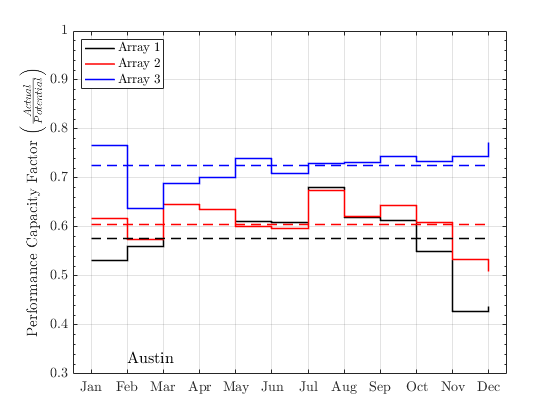


figure
stairs(reordercats(Month,cellstr(Month)'),CF(1,:)./I_Ref_12,'k','LineWidth',1.5)
hold on
stairs(reordercats(Month,cellstr(Month)'),CF(2,:)./I_Ref_12,'r','LineWidth',1.5)
stairs(reordercats(Month,cellstr(Month)'),CF(3,:)./I_Ref_3,'b','LineWidth',1.5)
stairs(Month([1 end]),ones(1,2)*mean(CF(1,:)./I_Ref_12),'--k','LineWidth',1.5)
stairs(Month([1 end]),ones(1,2)*mean(CF(2,:)./I_Ref_12),'--r','LineWidth',1.5)
stairs(Month([1 end]),ones(1,2)*mean(CF(3,:)./I_Ref_3),'--b','LineWidth',1.5)

ylabel('Performance Capacity Factor $\Big( \frac{Actual}{Potential} \Big)$','Interpreter','latex')
grid on
set(gca,'XMinorTick','on','YMinorTick','on')
set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',...
    0.13,'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')
legend('Array 1','Array 2','Array 3','location','NW','interpreter','latex')
xtickangle(0)
text(2,0.33,'Austin','Color',[0 0 0],'Interpreter','latex','FontSize',16)
ylim([0.3 1])

% print('-dpng','-r400','Performance_CF_Patzek.png')

% Overall mean
mean([mean(CF(1,:)./I_Ref_12)
mean(CF(2,:)./I_Ref_12)
mean(CF(3,:)./I_Ref_3)])

ans = 0.6359